% Path 2 Data
Path2AllData = '/Volumes/Julie4T/Results';
addpath(genpath('/Users/elie/Documents/CODE/GeneralCode'))
ADBitVolts_sorting=500/32767; %Conversion value used in mat2ntt for proper ploting under spikesort3D in AD count
% Let's find the date of interest in the Google sheet
% Path2RecordingTable = '/Users/elie/Google Drive/BatmanData/RecordingLogs/recording_logs.xlsx';
% [~,~,RecTableData]=xlsread(Path2RecordingTable,1,'A1:AF200','basic');
% Header = RecTableData(1,:);
% ND_IDCol = find(contains(Header, 'Neural data voc in operant + PSTH'));
% BatIDCol = find(contains(Header, 'Bat'));
% NLCol = find(contains(Header, 'NL'));
% Dates_Ind = find(cell2mat(RecTableData(2:end,ND_IDCol))==1)+1;
% Dates = cell2mat(RecTableData(Dates_Ind,1));
ThreshSig=50;

## Loop through spike sorting units and evaluate quality

SubjectID = '59834';
ListSSU = dir(fullfile(Path2AllData, sprintf('%s*.mat',SubjectID)));
NU = length(ListSSU);
% get rid fo files that corresponds to individual experiments
Data2Keep = nan(1,NU);
for ss=1:NU
    Data2Keep(ss) = length(strfind(ListSSU(ss).name, '_'))==3;
end
ListSSU = ListSSU(find(Data2Keep));
NU = length(ListSSU);

SSQ = cell(NU,1);
SNR = nan(NU,1);
ContamInd = nan(NU,1);
ISIViolation = nan(NU,1);
for ss=1:NU
    fprintf(1,'File %d/%d\n',ss,NU)
    [~,FileName] = fileparts(ListSSU(ss).name);
%     Ind_ = strfind(FileName,'_');
%     SubjectID = FileName(1:5);
%     Date = FileName(7:14);
%     TetrodeID = FileName(Ind_(3)+1);
%     SSQ = FileName(Ind_(3)-1);
%     Ind__ = strfind(FileName,'-');
%     SSID = FileName(Ind__:end);
    Data=load(fullfile(ListSSU(ss).folder,ListSSU(ss).name));
    SNR(ss) = max(Data.QualitySSU.SNR);
    ContamInd(ss) = Data.QualitySSU.ContamInd;
    ISIViolation(ss) = Data.QualitySSU.ISIViolation;
    if (SNR(ss)>=6) && (ISIViolation(ss)<=1) && (ContamInd(ss)<=0.2)
        SSQ{ss} = 'SSSU';
    elseif (SNR(ss)>=2)
        SSQ{ss} = 'SSMU';
    else
        SSQ{ss} = 'NOISE';
    end
end

File 1/348
File 2/348
File 3/348
File 4/348
File 5/348
File 6/348
File 7/348
File 8/348
File 9/348
File 10/348
File 11/348
File 12/348
File 13/348
File 14/348
File 15/348
File 16/348
File 17/348
File 18/348
File 19/348
File 20/348
File 21/348
File 22/348
File 23/348
File 24/348
File 25/348
File 26/348
File 27/348
File 28/348
File 29/348
File 30/348
File 31/348
File 32/348
File 33/348
File 34/348
File 35/348
File 36/348
File 37/348
File 38/348
File 39/348
File 40/348
File 41/348
File 42/348
File 43/348
File 44/348
File 45/348
File 46/348
File 47/348
File 48/348
File 49/348
File 50/348
File 51/348
File 52/348
File 53/348
File 54/348
File 55/348
File 56/348
File 57/348
File 58/348
File 59/348
File 60/348
File 61/348
File 62/348
File 63/348
File 64/348
File 65/348
File 66/348
File 67/348
File 68/348
File 69/348
File 70/348
File 71/348
File 72/348
File 73/348
File 74/348
File 75/348
File 76/348
File 77/348
File 78/348
File 79/348
File 80/348
File 81/348
File 82/348
File 83/348
File 84/348
F

SSSU = (SNR>=5) .* (ISIViolation<=1) .* (ContamInd<=0.2);
SSMU = ~SSSU .* (SNR>=2);
NOISE = SNR<2;
C = [NOISE SSSU SSMU];
fprintf('Number of single units: %d/%d, %.2f%%\n',sum(SSSU), NU,sum(SSSU)/NU*100)

Number of single units: 107/348, 30.75%


fprintf('Number of multi-units: %d/%d, %.2f%%\n',sum(SSMU), NU,sum(SSMU)/NU*100)

Number of multi-units: 239/348, 68.68%


fprintf('Number of Noise units: %d/%d, %.2f%%\n',sum(NOISE), NU,sum(NOISE)/NU*100)

Number of Noise units: 2/348, 0.57%


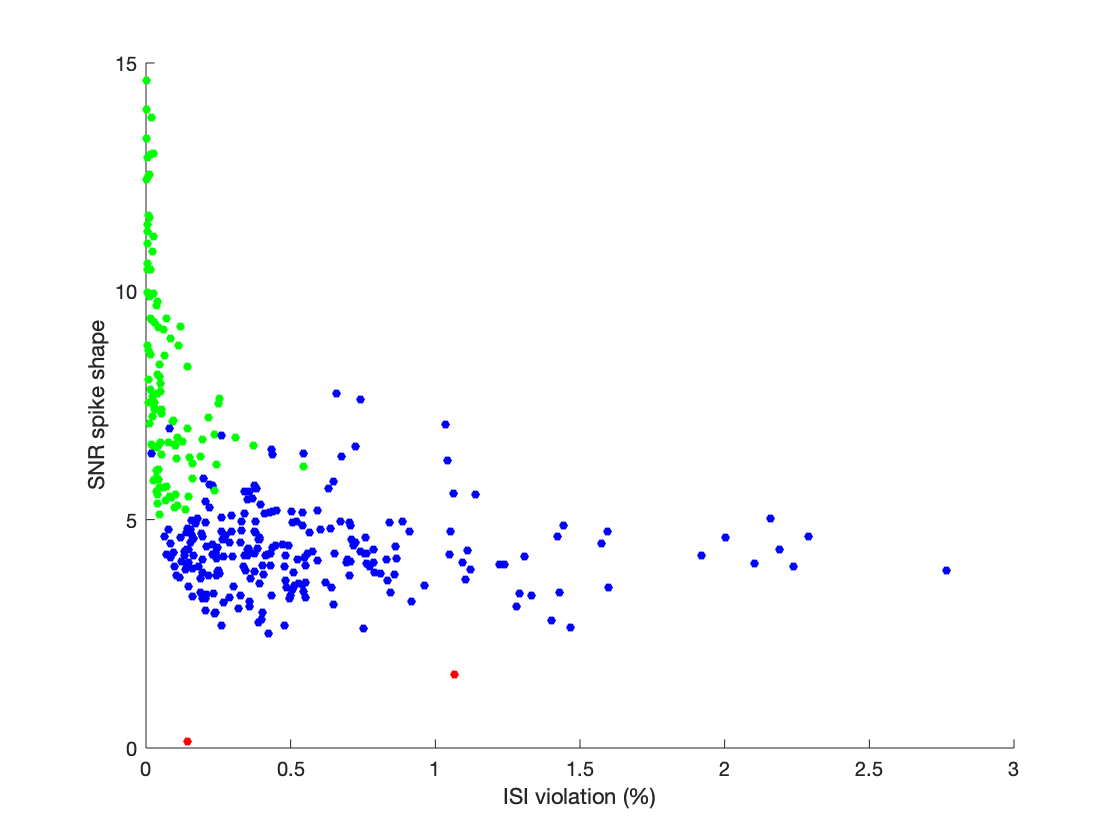


% GoodCellIndices = find(contains(SSQ, 'SS'));

% C = [contains(SSQ, 'NOISE') contains(SSQ, 'SSSU') contains(SSQ, 'SSMU')];
scatter(ISIViolation, SNR,20,C,'filled')
xlabel('ISI violation (%)')
ylabel('SNR spike shape')

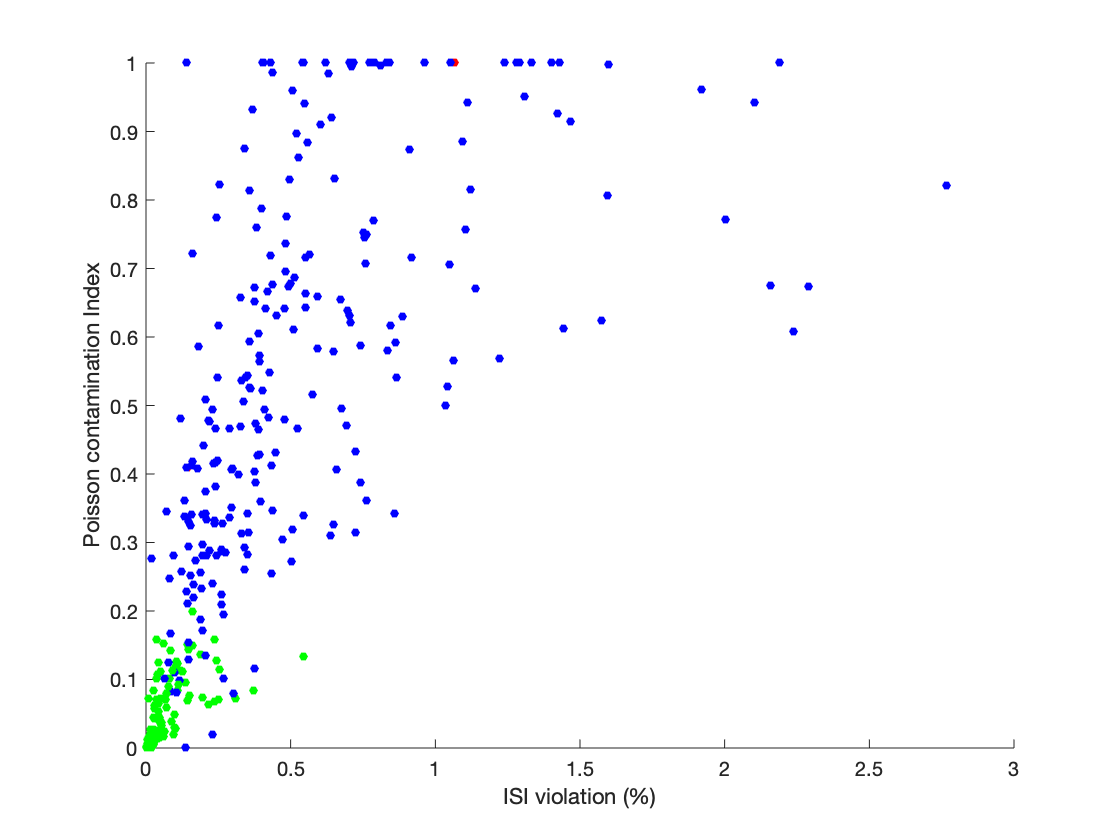

ContamInd(ContamInd>1)=1; %saturate the ContamInd, everything above 1 is just highly contaminated
scatter(ISIViolation,ContamInd, 20, C,'filled')
xlabel('ISI violation (%)')
ylabel('Poisson contamination Index')

## Hierarchical clustering on KDE onset of all cells for Ba and Tr

% gather the data
Tstart = -3000;
GoodCellIndices = sort([find(SSSU); find(SSMU)]);
GC = length(GoodCellIndices);
KDE_onset = cell(GC,3);
T_onset = cell(GC,2);
Tmax = nan(GC,2);
MeanKDE = nan(GC,1);
for ss=1:GC
    fprintf(1,'File %d/%d\n',ss,GC)
    [~,FileName] = fileparts(ListSSU(GoodCellIndices(ss)).name);
    Data=load(fullfile(ListSSU(GoodCellIndices(ss)).folder,ListSSU(GoodCellIndices(ss)).name));
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfBaOp')
        Tmax(ss,1) = max(Data.KDE_onset.SelfBaOp(2,:));
        KDE_onset{ss,1} = Data.KDE_onset.SelfBaOp(1,find(Data.KDE_onset.SelfBaOp(2,:)==Tstart):end);
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfTrOp')
        Tmax(ss,2) = max(Data.KDE_onset.SelfTrOp(2,:));
        KDE_onset{ss,2} = Data.KDE_onset.SelfTrOp(1,find(Data.KDE_onset.SelfTrOp(2,:)==Tstart):end);
    end
    if isfield(Data,'KDE_onset') && isfield(Data.KDE_onset, 'SelfVocOp')
        KDE_onset{ss,3} = Data.KDE_onset.SelfVocOp(1,find(Data.KDE_onset.SelfVocOp(2,:)==Tstart):end);
        MeanKDE(ss) = nanmean(Data.KDE_onset.SelfVocOp(1,find(Data.KDE_onset.SelfVocOp(2,:)==Tstart):end)); 
    end
end

File 1/346
File 2/346
File 3/346
File 4/346
File 5/346
File 6/346
File 7/346
File 8/346
File 9/346
File 10/346
File 11/346
File 12/346
File 13/346
File 14/346
File 15/346
File 16/346
File 17/346
File 18/346
File 19/346
File 20/346
File 21/346
File 22/346
File 23/346
File 24/346
File 25/346
File 26/346
File 27/346
File 28/346
File 29/346
File 30/346
File 31/346
File 32/346
File 33/346
File 34/346
File 35/346
File 36/346
File 37/346
File 38/346
File 39/346
File 40/346
File 41/346
File 42/346
File 43/346
File 44/346
File 45/346
File 46/346
File 47/346
File 48/346
File 49/346
File 50/346
File 51/346
File 52/346
File 53/346
File 54/346
File 55/346
File 56/346
File 57/346
File 58/346
File 59/346
File 60/346
File 61/346
File 62/346
File 63/346
File 64/346
File 65/346
File 66/346
File 67/346
File 68/346
File 69/346
File 70/346
File 71/346
File 72/346
File 73/346
File 74/346
File 75/346
File 76/346
File 77/346
File 78/346
File 79/346
File 80/346
File 81/346
File 82/346
File 83/346
File 84/346
F

% Trim the data in time and create a matrix of all the KDE

BaTr_0ind = ~isnan(Tmax(:,1)) .* ~isnan(Tmax(:,2)).* ~isnan(MeanKDE);
BaTr_ind = find(BaTr_0ind);
fprintf('The clustering algorithm can be performed on the data of %d/%d\n',sum(BaTr_0ind),GC)

The clustering algorithm can be performed on the data of 258/346


TBa = length(Tstart:min(Tmax(:,1)));
TTr = length(Tstart:min(Tmax(:,2)));
KDE_onset_Mat_BaTr = nan(sum(BaTr_0ind),TBa + TTr);
for ss=1:sum(BaTr_0ind)
    fprintf(1,'File %d/%d\n',ss,sum(BaTr_0ind))
    KDE_onset_Mat_BaTr(ss,:) = [KDE_onset{BaTr_ind(ss),1}(1:TBa) KDE_onset{BaTr_ind(ss),2}(1:TTr)]-MeanKDE(BaTr_ind(ss));
end

File 1/258
File 2/258
File 3/258
File 4/258
File 5/258
File 6/258
File 7/258
File 8/258
File 9/258
File 10/258
File 11/258
File 12/258
File 13/258
File 14/258
File 15/258
File 16/258
File 17/258
File 18/258
File 19/258
File 20/258
File 21/258
File 22/258
File 23/258
File 24/258
File 25/258
File 26/258
File 27/258
File 28/258
File 29/258
File 30/258
File 31/258
File 32/258
File 33/258
File 34/258
File 35/258
File 36/258
File 37/258
File 38/258
File 39/258
File 40/258
File 41/258
File 42/258
File 43/258
File 44/258
File 45/258
File 46/258
File 47/258
File 48/258
File 49/258
File 50/258
File 51/258
File 52/258
File 53/258
File 54/258
File 55/258
File 56/258
File 57/258
File 58/258
File 59/258
File 60/258
File 61/258
File 62/258
File 63/258
File 64/258
File 65/258
File 66/258
File 67/258
File 68/258
File 69/258
File 70/258
File 71/258
File 72/258
File 73/258
File 74/258
File 75/258
File 76/258
File 77/258
File 78/258
File 79/258
File 80/258
File 81/258
File 82/258
File 83/258
File 84/258
F

Z = linkage(KDE_onset_Mat_BaTr,'ward','euclidean')

Z = 	1.0e+03 *

    0.1110    0.1130         0
    0.0190    0.0220         0
    0.0140    0.2600         0
    0.0830    0.0890         0
    0.2590    0.2610    0.0001
    0.2620    0.2630    0.0003
    0.0280    0.2640    0.0107
    0.0240    0.2470    0.0245
    0.0600    0.2650    0.0430
    0.0700    0.2110    0.0449


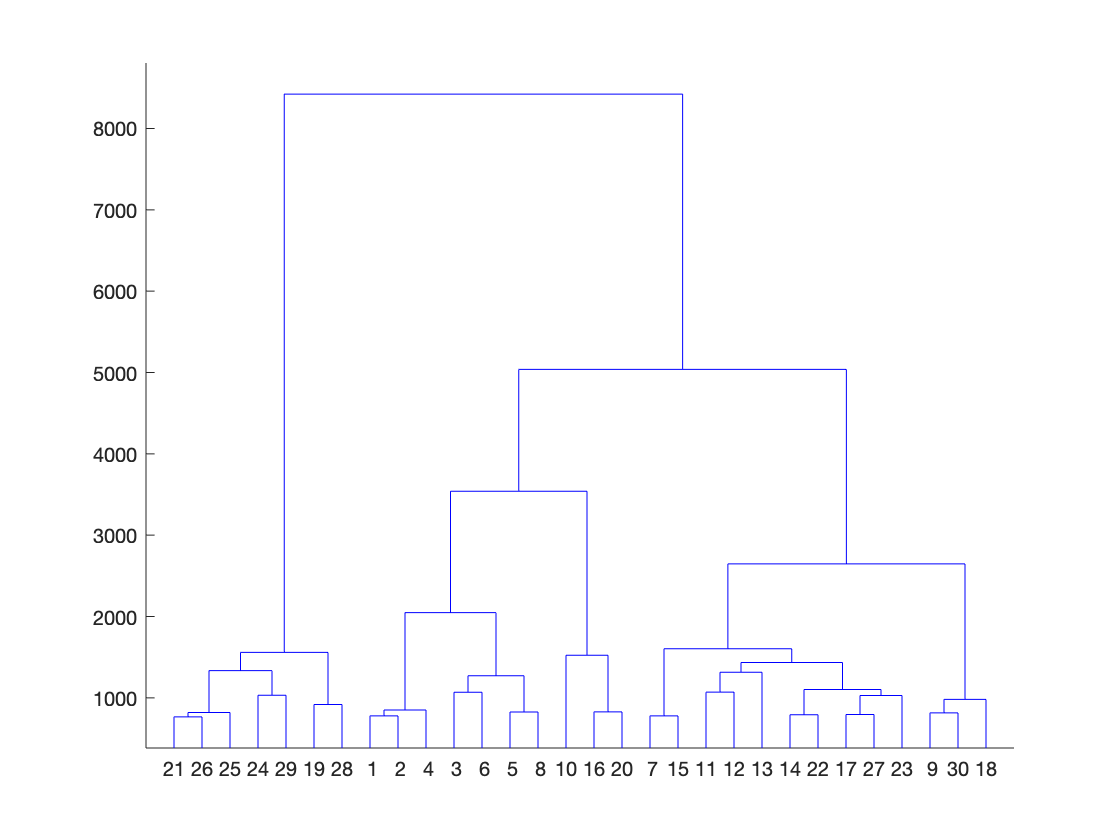

dendrogram(Z)

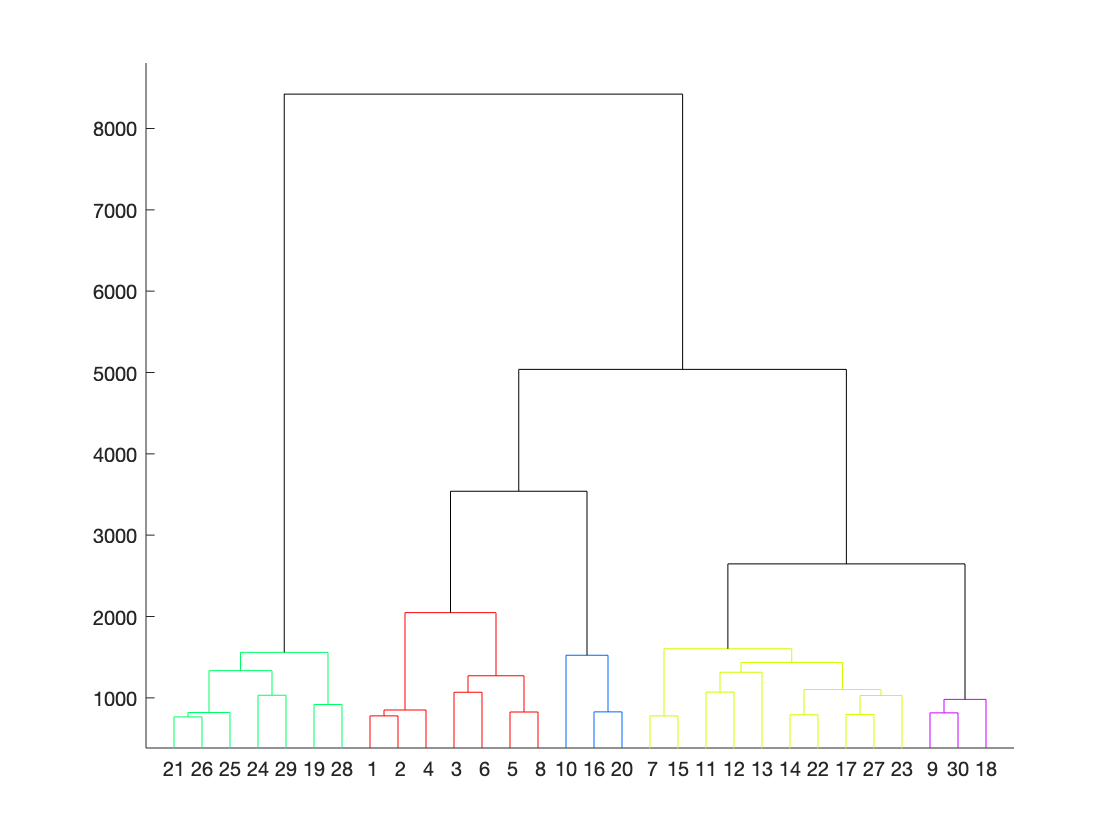

T = cluster(Z,'maxclust',5);
cutoff = median([Z(end-4,3) Z(end-3,3)]);
dendrogram(Z,'ColorThreshold',cutoff)

Plot the average spike rate for each cluster

% cluster 1
Clust=1;
IndSSU = intersect(GoodCellIndices(T==Clust), find(SSSU));
IndSMU = intersect(GoodCellIndices(T==Clust), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))

**** Cluster 1 *****
5 units, 0 single units, 5 multi-units


for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end
for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end

Multi Unit: 59834_20190604_SSM_4-241.mat
Multi Unit: 59834_20190605_SSM_1-91.mat
Multi Unit: 59834_20190606_SSM_3-112.mat
Multi Unit: 59834_20190611_SSM_3-190.mat
Multi Unit: 59834_20190612_SSM_1-75.mat


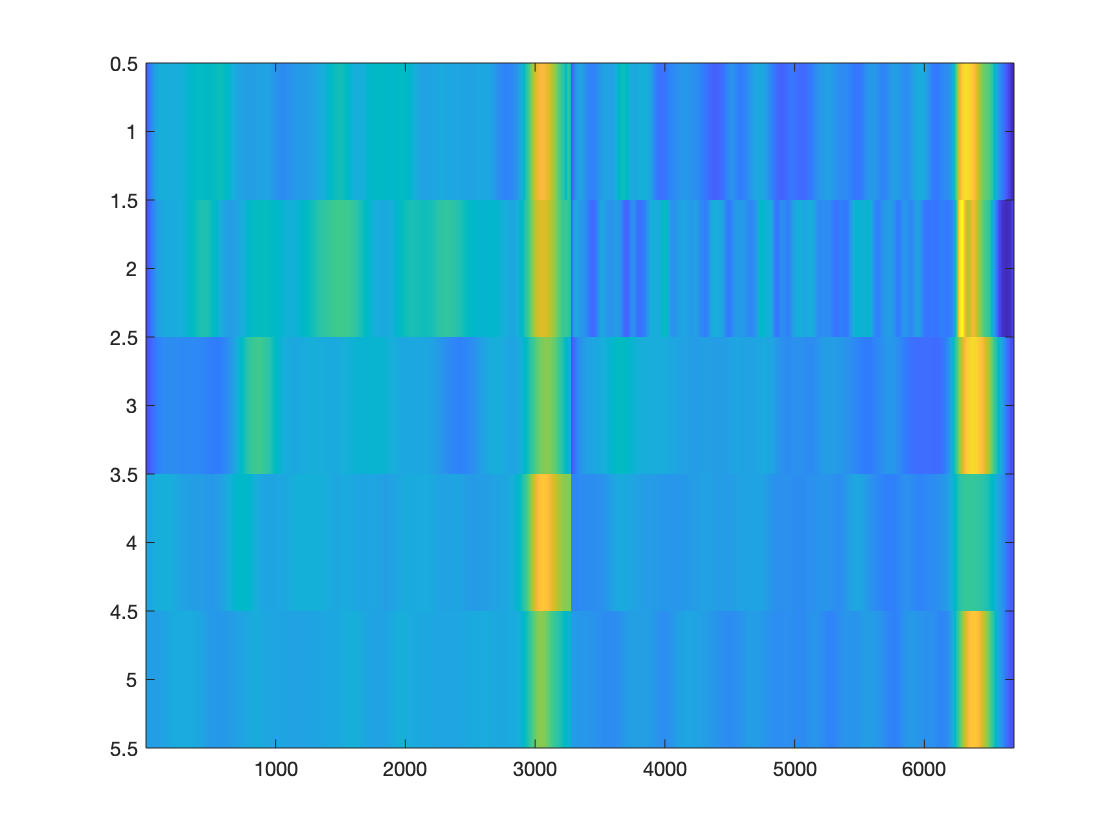

imagesc(KDE_onset_Mat_BaTr(T==Clust,:))


% cluster 2 good example: 0612_SSS_1-81
Clust=2;
IndSSU = intersect(GoodCellIndices(T==Clust), find(SSSU));
IndSMU = intersect(GoodCellIndices(T==Clust), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))

**** Cluster 2 *****
32 units, 16 single units, 16 multi-units


for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end

Single Unit: 59834_20190604_SSS_3-109.mat
Single Unit: 59834_20190605_SSS_2-185.mat
Single Unit: 59834_20190607_SSS_1-139.mat
Single Unit: 59834_20190611_SSS_1-183.mat
Single Unit: 59834_20190611_SSS_2-222.mat
Single Unit: 59834_20190612_SSS_1-81.mat
Single Unit: 59834_20190616_SSS_3-137.mat
Single Unit: 59834_20190617_SSS_2-167.mat
Single Unit: 59834_20190617_SSS_3-174.mat
Single Unit: 59834_20190618_SSS_2-160.mat
Single Unit: 59834_20190618_SSS_2-188.mat
Single Unit: 59834_20190618_SSS_2-99.mat
Single Unit: 59834_20190619_SSS_2-148.mat
Single Unit: 59834_20190619_SSS_3-168.mat
Single Unit: 59834_20190620_SSS_1-81.mat
Single Unit: 59834_20190622_SSS_1-84.mat


for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end

Multi Unit: 59834_20190604_SSM_3-229.mat
Multi Unit: 59834_20190607_SSM_1-153.mat
Multi Unit: 59834_20190607_SSM_2-201.mat
Multi Unit: 59834_20190611_SSM_2-220.mat
Multi Unit: 59834_20190612_SSM_2-101.mat
Multi Unit: 59834_20190613_SSM_2-117.mat
Multi Unit: 59834_20190614_SSM_3-184.mat
Multi Unit: 59834_20190618_SSM_2-189.mat
Multi Unit: 59834_20190619_SSM_2-134.mat
Multi Unit: 59834_20190619_SSM_3-158.mat
Multi Unit: 59834_20190620_SSM_2-101.mat
Multi Unit: 59834_20190621_SSM_1-84.mat
Multi Unit: 59834_20190622_SSM_3-162.mat
Multi Unit: 59834_20190623_SSM_1-104.mat
Multi Unit: 59834_20190623_SSS_4-220.mat
Multi Unit: 59834_20190624_SSM_3-181.mat


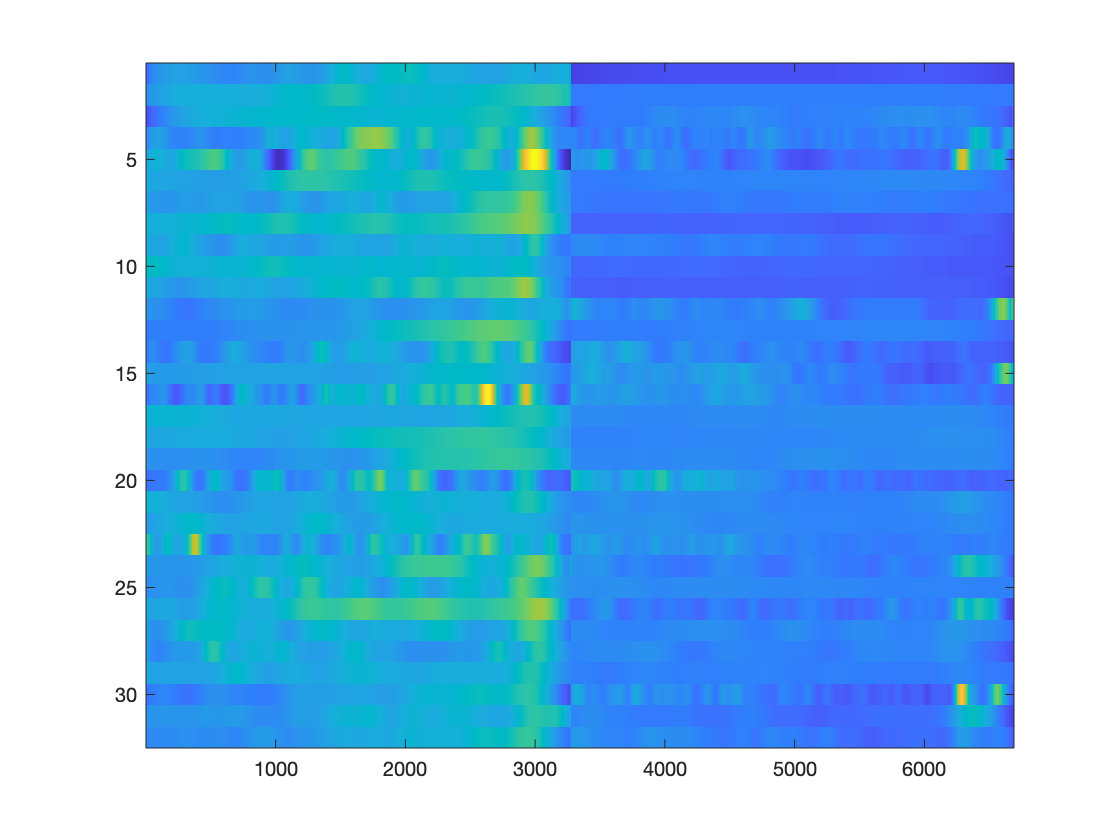

imagesc(KDE_onset_Mat_BaTr(T==Clust,:))


% cluster 3 good example 0620_SSS_3_131
Clust=3;
IndSSU = intersect(GoodCellIndices(T==Clust), find(SSSU));
IndSMU = intersect(GoodCellIndices(T==Clust), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))

**** Cluster 3 *****
31 units, 9 single units, 22 multi-units


for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end

Single Unit: 59834_20190611_SSS_1-97.mat
Single Unit: 59834_20190614_SSS_2-210.mat
Single Unit: 59834_20190616_SSS_1-77.mat
Single Unit: 59834_20190616_SSS_2-125.mat
Single Unit: 59834_20190617_SSS_2-94.mat
Single Unit: 59834_20190619_SSS_1-78.mat
Single Unit: 59834_20190619_SSS_4-222.mat
Single Unit: 59834_20190620_SSS_3-131.mat
Single Unit: 59834_20190621_SSS_2-124.mat


for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end

Multi Unit: 59834_20190604_SSM_4-243.mat
Multi Unit: 59834_20190605_SSM_1-183.mat
Multi Unit: 59834_20190612_SSS_3-157.mat
Multi Unit: 59834_20190614_SSM_1-203.mat
Multi Unit: 59834_20190614_SSM_2-126.mat
Multi Unit: 59834_20190614_SSM_2-140.mat
Multi Unit: 59834_20190617_SSM_1-78.mat
Multi Unit: 59834_20190619_SSM_1-86.mat
Multi Unit: 59834_20190619_SSM_1-98.mat
Multi Unit: 59834_20190619_SSS_4-208.mat
Multi Unit: 59834_20190619_SSS_4-216.mat
Multi Unit: 59834_20190619_SSS_4-234.mat
Multi Unit: 59834_20190622_SSM_1-202.mat
Multi Unit: 59834_20190623_SSM_2-118.mat
Multi Unit: 59834_20190623_SSM_2-130.mat
Multi Unit: 59834_20190623_SSM_3-188.mat
Multi Unit: 59834_20190624_SSM_1-117.mat
Multi Unit: 59834_20190624_SSM_2-135.mat
Multi Unit: 59834_20190624_SSM_3-209.mat
Multi Unit: 59834_20190625_SSM_2-169.mat
Multi Unit: 59834_20190625_SSM_2-177.mat
Multi Unit: 59834_20190625_SSM_3-249.mat


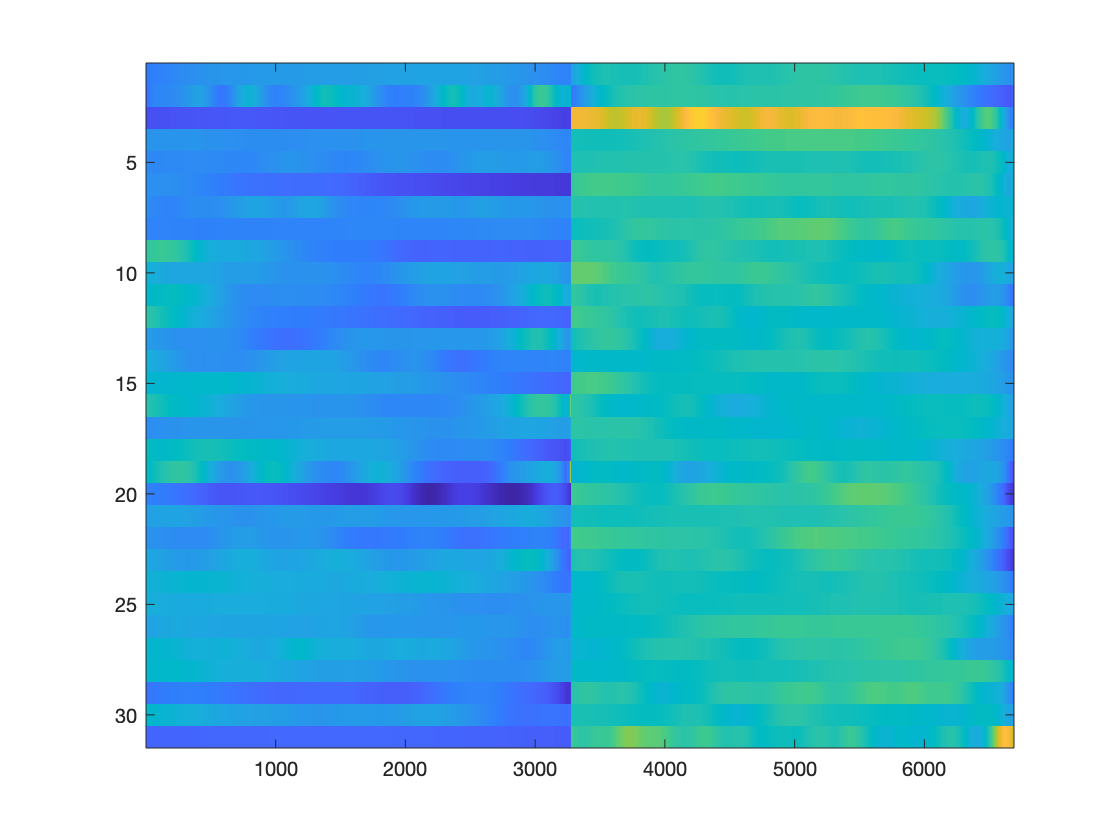

imagesc(KDE_onset_Mat_BaTr(T==Clust,:))


% cluster 4
Clust=4;
IndSSU = intersect(GoodCellIndices(T==Clust), find(SSSU));
IndSMU = intersect(GoodCellIndices(T==Clust), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))

**** Cluster 4 *****
179 units, 53 single units, 126 multi-units


for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end

Single Unit: 59834_20190604_SSS_4-193.mat
Single Unit: 59834_20190605_SSS_4-159.mat
Single Unit: 59834_20190605_SSS_4-163.mat
Single Unit: 59834_20190605_SSS_4-167.mat
Single Unit: 59834_20190606_SSS_1-76.mat
Single Unit: 59834_20190606_SSS_4-122.mat
Single Unit: 59834_20190607_SSS_2-189.mat
Single Unit: 59834_20190610_SSS_1-130.mat
Single Unit: 59834_20190611_SSS_1-117.mat
Single Unit: 59834_20190611_SSS_2-216.mat
Single Unit: 59834_20190611_SSS_3-137.mat
Single Unit: 59834_20190611_SSS_3-161.mat
Single Unit: 59834_20190611_SSS_3-181.mat
Single Unit: 59834_20190612_SSM_2-196.mat
Single Unit: 59834_20190612_SSS_2-109.mat
Single Unit: 59834_20190612_SSS_2-93.mat
Single Unit: 59834_20190612_SSS_3-191.mat
Single Unit: 59834_20190612_SSS_3-193.mat
Single Unit: 59834_20190612_SSS_3-22.mat
Single Unit: 59834_20190613_SSS_1-11.mat
Single Unit: 59834_20190613_SSS_2-105.mat
Single Unit: 59834_20190613_SSS_3-127.mat
Single Unit: 59834_20190613_SSS_3-141.mat
Single Unit: 59834_20190614_SSS_1-100.

for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end

Multi Unit: 59834_20190604_SSM_1-201.mat
Multi Unit: 59834_20190604_SSM_1-206.mat
Multi Unit: 59834_20190604_SSM_1-233.mat
Multi Unit: 59834_20190604_SSM_2-208.mat
Multi Unit: 59834_20190604_SSM_3-115.mat
Multi Unit: 59834_20190604_SSM_3-213.mat
Multi Unit: 59834_20190604_SSM_4-135.mat
Multi Unit: 59834_20190604_SSS_3-111.mat
Multi Unit: 59834_20190604_SSS_3-191.mat
Multi Unit: 59834_20190604_SSS_4-197.mat
Multi Unit: 59834_20190605_SSM_1-179.mat
Multi Unit: 59834_20190605_SSM_1-97.mat
Multi Unit: 59834_20190605_SSM_2-109.mat
Multi Unit: 59834_20190605_SSM_2-139.mat
Multi Unit: 59834_20190605_SSM_4-190.mat
Multi Unit: 59834_20190605_SSS_4-149.mat
Multi Unit: 59834_20190606_SSM_1-124.mat
Multi Unit: 59834_20190606_SSM_1-84.mat
Multi Unit: 59834_20190607_SSM_1-203.mat
Multi Unit: 59834_20190607_SSM_2-175.mat
Multi Unit: 59834_20190607_SSM_2-183.mat
Multi Unit: 59834_20190610_SSM_1-143.mat
Multi Unit: 59834_20190611_SSM_1-87.mat
Multi Unit: 59834_20190611_SSM_3-186.mat
Multi Unit: 59834_2

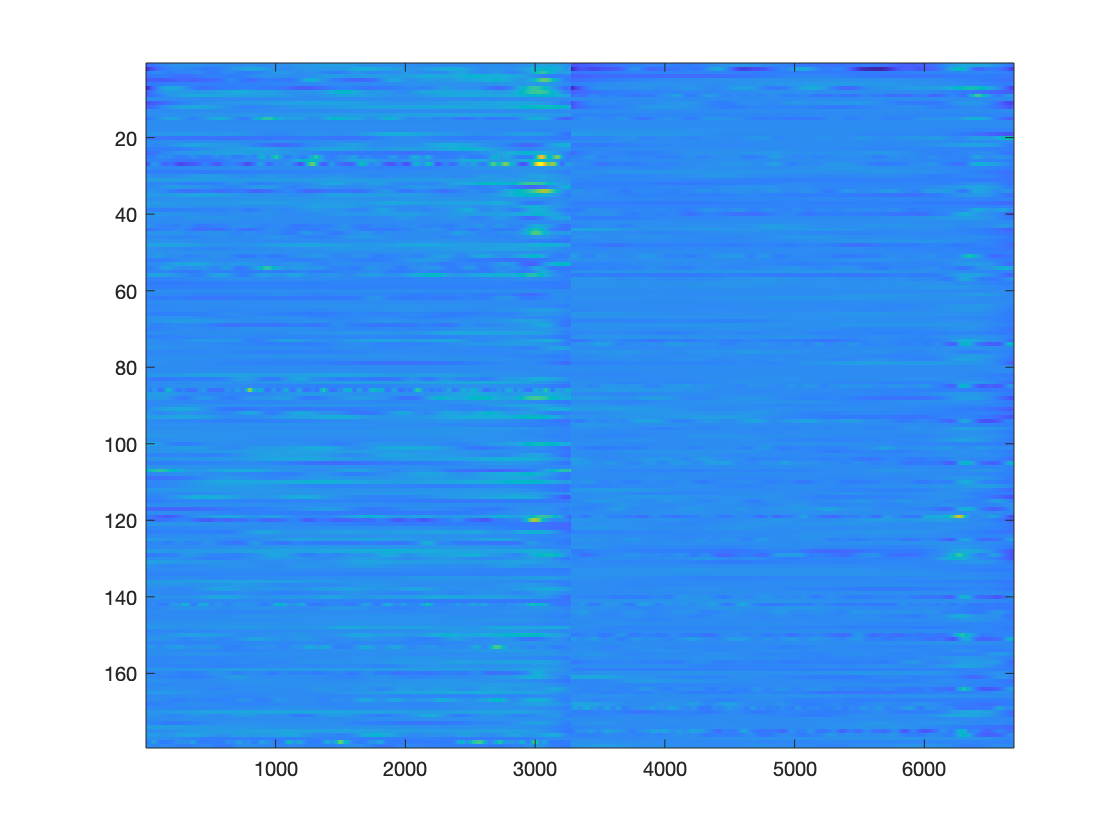

imagesc(KDE_onset_Mat_BaTr(T==Clust,:))


% cluster 5
Clust=5;
IndSSU = intersect(GoodCellIndices(T==Clust), find(SSSU));
IndSMU = intersect(GoodCellIndices(T==Clust), find(SSMU));
fprintf(1,'**** Cluster %d *****\n%d units, %d single units, %d multi-units\n', Clust, sum(T==Clust),length(IndSSU),length(IndSMU))

**** Cluster 5 *****
11 units, 2 single units, 9 multi-units


for ii=1:length(IndSSU)
    fprintf('Single Unit: %s\n',ListSSU(IndSSU(ii)).name)
end

Single Unit: 59834_20190617_SSS_3-155.mat
Single Unit: 59834_20190619_SSS_2-108.mat


for ii=1:length(IndSMU)
    fprintf('Multi Unit: %s\n',ListSSU(IndSMU(ii)).name)
end

Multi Unit: 59834_20190613_SSM_3-123.mat
Multi Unit: 59834_20190616_SSS_2-131.mat
Multi Unit: 59834_20190620_SSM_4-193.mat
Multi Unit: 59834_20190621_SSM_2-106.mat
Multi Unit: 59834_20190622_SSS_2-148.mat
Multi Unit: 59834_20190623_SSM_3-194.mat
Multi Unit: 59834_20190624_SSM_3-239.mat
Multi Unit: 59834_20190624_SSM_4-229.mat
Multi Unit: 59834_20190625_SSM_3-258.mat


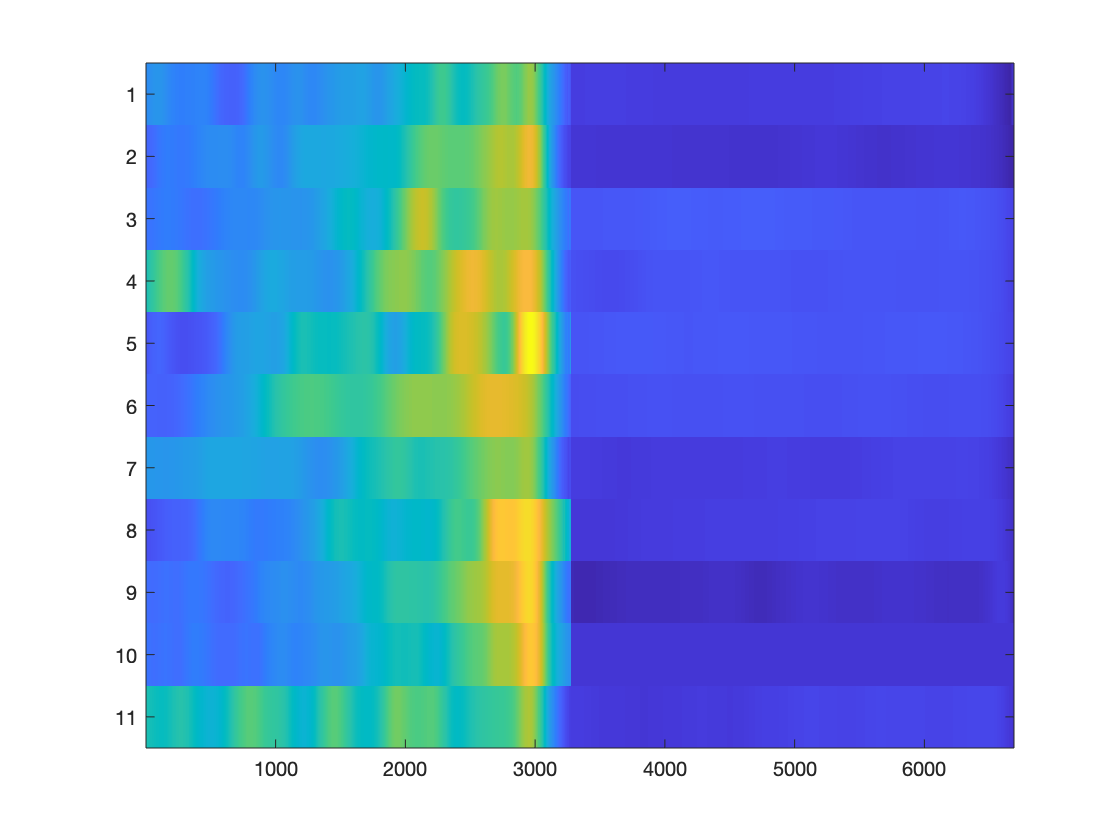

imagesc(KDE_onset_Mat_BaTr(T==Clust,:))


% For each day, each logger, each unit find the average spike rate
PLOT=1;
MeanSR4Calulations = 1; % Values in Hz of the mean SR for doing calculations
NDays = length(Dates);
HypNSU = 200;
TimeStep = 10*60; % Time resolution in seconds at which the spike rate shoule be calculated
MaxRecTime = 60*60*6;
TimePoints = 0:TimeStep:MaxRecTime;
SpikeRate = nan(HypNSU,length(TimePoints)-1);% will contain spike rate in Hz
KDE = nan(HypNSU,length(TimePoints)-1);% will contain spike rate in Hz
KDE_error = cell(HypNSU,1);% will contain spike rate error in Hz
Peak2Peak = nan(HypNSU,length(TimePoints)-1);% will contain mean spike amplitude along time
SpikeLife = nan(HypNSU,1); % Duration in minutes of period containing a spike from the cell
SD_SR = nan(HypNSU,1);
Mean_SR = nan(HypNSU,1); % average mean SR in Hz of each cell only counting time windows of 10min where there is at least one spike (cell still active)
Bat_ID = nan(HypNSU,1);
Date_ID = nan(HypNSU,1);
Tetrode_ID = nan(HypNSU,1);
SS_ID = cell(HypNSU,1);
Mean_Peak2Peak = nan(HypNSU,1);
SpikeShape = cell(HypNSU,4);
Alpha = 0.01; % Detection thershold for significant spike rate modulation before correction for false positive
SignWinVoc = nan(HypNSU,1); % number of time bin in the KDE when producing the vocalizations above the mean baseline firing rate by twice the SD of the baseline firing rate
SignWinHear = nan(HypNSU,1);% number of time bin in the KDE when hearing the vocalizations above the mean baseline firing rate by twice the SD of the baseline firing rate
ProdCellGood = nan(HypNSU,1);

CellCount=0;
for dd=1:NDays
    Date = Dates(dd);
    fprintf(1,'%d\n',Date)
    Path2Data = fullfile(Path2AllData, ['20' num2str(Date)]);
    % Get the number of loggers
    Logger_dirs = dir(fullfile(Path2Data, '*ogger*'));
    Logger_dirs=Logger_dirs([Logger_dirs.isdir]);
    NLogger = length(Logger_dirs);
    % Identify the type of logger and extract neural data
    LoggerType = cell(NLogger,1);
    % LOAD the data of KDE to do a test for vocalization production
    FileData = dir(fullfile(Path2Data, sprintf('%d_*_VocExtractData_*', Date)));
    load(fullfile(FileData(1).folder,FileData(1).name), 'SpikeTimesVoc')
    Ind_ = strfind(FileData(1).name, '_');
    Delay = str2double(FileData(1).name(Ind_(end) + (1:3)));
    for ll=1:NLogger
        fprintf(1,'%s\n',Logger_dirs(ll).name)
        LData_folder = fullfile(Logger_dirs(ll).folder, Logger_dirs(ll).name,'extracted_data');
        LDir = dir(fullfile(LData_folder, '*CSC*.mat'));
        LData = load(fullfile(LDir(1).folder, LDir(1).name), 'logger_type', 'logger_serial_number');
        LoggerType{ll}  = LData.logger_type;
        if strcmp(LoggerType{ll}, 'Mous') || strcmp(LoggerType{ll}, 'Rat')
            SU_files = dir(fullfile(LData_folder, '*TT*SS*.mat'));
            NSU = length(SU_files);
            %Get the Bat-ID for that logger
            RowData = find((cell2mat(RecTableData(2:end,1))== Date)) +1;
            DataInfo = RecTableData(RowData,:);
            NL_ID = cell2mat(DataInfo(NLCol));
            NLCol_local = NLCol(NL_ID==str2double(LData.logger_serial_number));
            Bat_ID_local = DataInfo{BatIDCol(find(BatIDCol<NLCol_local,1,'last'))};
            if Bat_ID_local==11689 % Only run on Hodor

                for uu=1:NSU
                    CellCount = CellCount+1;
                    fprintf(1,'Cell %d\n',CellCount)
                    Cell = load(fullfile(SU_files(uu).folder, SU_files(uu).name)); % This load the Spike_arrival_times in micro seconds and the Spike_snippets in microVolts, ceiled at 500uV for spike sorting projection
                    SpikeTimes = (Cell.Spike_arrival_times-Cell.Spike_arrival_times(1))*10^-6; % Spike arrival times centered to the first spike, in seconds

                    % Find the best channel to calculate the peak2peak value
                    % (channel with largest spike trace)
                    P2P_all = nan(size(Cell.Spike_snippets,3),4);
                    for cc=1:4 % calculate for each channel the peak2peak for all spikes
                        P2P_all(:,cc)=reshape(max(Cell.Spike_snippets(:,cc,:),[],1) - min(Cell.Spike_snippets(:,cc,:),[],1),size(Cell.Spike_snippets,3),1);
                    end
                    [~,I]=max(P2P_all,[],2);
                    Best_c = nan(1,4);
                    for cc=1:4
                        Best_c(cc) = sum(I==cc);
                    end
                    [~,Best_c] = max(Best_c); % This is the channel with the largest spike


                    for tt=1:(length(TimePoints)-1)
                        Spike_local = (SpikeTimes>=TimePoints(tt)) .* (SpikeTimes<=TimePoints(tt+1));
                        SpikeRate(CellCount,tt) = sum(Spike_local)/TimeStep; % this is the local spike rate in Hertz
                        SpikeInd = find(Spike_local);
                        % calculate for each channel the average peak2peak for the spikes occuring during that time slot
                        Peak2Peak(CellCount,tt) = ADBitVolts_sorting.*mean(max(Cell.Spike_snippets(:,Best_c,SpikeInd),[],1) - min(Cell.Spike_snippets(:,Best_c,SpikeInd),[],1));
                    end



                    % calculate average statistics for that cell
                    SpikeLife(CellCount) = (TimePoints(find(~isnan(Peak2Peak(CellCount,:)),1,'Last'))- TimePoints(find(~isnan(Peak2Peak(CellCount,:)),1,'First')))/60;
                    [KDE(CellCount,:),~,KDE_error{CellCount}] = kde_wrapper(SpikeTimes,TimePoints(2:end)-TimeStep/2,1/TimeStep);
                    Mean_Peak2Peak(CellCount) = mean(P2P_all(:,Best_c));
                    Mean_SR(CellCount) = mean(SpikeRate(CellCount,find(~isnan(Peak2Peak(CellCount,:)))));
                    SD_SR(CellCount) = std(SpikeRate(CellCount,find(~isnan(Peak2Peak(CellCount,:)))));
                    Bat_ID(CellCount) = Bat_ID_local;
                    Date_ID(CellCount) = str2double(['20' num2str(Date)]);
                    TTInd = strfind(SU_files(uu).name, 'TT');
                    Tetrode_ID(CellCount) = str2double(SU_files(uu).name(TTInd+2));
                    SSInd = strfind(SU_files(uu).name, 'SS');
                    SS_ID{CellCount} = SU_files(uu).name(SSInd+(3:4));

                    % extract the average spike shape for that cell
                    for cc=1:4
                        SpikeShape{CellCount,cc}=nan(2,size(Cell.Spike_snippets,1));
                        SpikeShape{CellCount,cc}(1,:) = mean(Cell.Spike_snippets(:,cc,:),3).*ADBitVolts_sorting;
                        SpikeShape{CellCount,cc}(2,:) = std(Cell.Spike_snippets(:,cc,:),0,3).*ADBitVolts_sorting;
                    end
                    
                    
                    % Test if the cell has a modulated spike rate compared to
                    % averaged before vocalizations (one time window with KDE
                    % away from the mean by twice SD). Rate is in spike per ms
                    % here. Test only if the average spike rate is  above 0.1Hz (1 spike every 10 seconds);
                    ST = SpikeTimesVoc.(sprintf('Logger%s',LData.logger_serial_number));
                    LogicalInd=logical((ST.Sum_Psth_KDEfiltered_VocCall{uu,1}>-Delay) .* (ST.Sum_Psth_KDEfiltered_VocCall{uu,1}<mean(ST.VocDuration+Delay)));
                    Fig0=figure(1);
                    clf(Fig0)
                    plot(ST.Sum_Psth_KDEfiltered_VocCall{uu,1}(LogicalInd), ST.Sum_Psth_KDEfiltered_VocCall{uu,2}(LogicalInd), '-k', 'LineWidth',2)
                    hold on
                    plot([min(ST.Sum_Psth_KDEfiltered_VocCall{uu,1}(LogicalInd)) max(ST.Sum_Psth_KDEfiltered_VocCall{uu,1}(LogicalInd))], MeanBaselineVoc/1000.* ones(2,1), ':r', 'LineWidth',2)
                    ylabel('Spike Rate (Hz)')
                    xlabel('Time (ms)')
                    legend('Rate','Background')
                    title(sprintf('Test for modulated spike rate M%d %d TT%d SS%s SU%d', Bat_ID(CellCount),Date_ID(CellCount), Tetrode_ID(CellCount), SS_ID{CellCount},uu))
                    
                    hold off
                    if Mean_SR(CellCount)>MeanSR4Calulations
                        if ~isempty(ST.Sum_Psth_KDEfiltered_VocBaseline) && iscell(ST.Sum_Psth_KDEfiltered_VocBaseline)
                            MeanBaselineVoc = mean(ST.Sum_Psth_KDEfiltered_VocBaseline{uu,2})*1000;% Average baseline rate in Hz
                            if MeanBaselineVoc>MeanSR4Calulations
                                Zscore = abs(ST.Sum_Psth_KDEfiltered_VocCall{uu,2}(LogicalInd) - MeanBaselineVoc/1000)/std(ST.Sum_Psth_KDEfiltered_VocBaseline{uu,2});
                                P_value = normcdf(Zscore, 'upper');
                                PV_sorted = sort(P_value);
                                
                                
                                % False Rate detection correction,
                                % Benjamini-Hochberg procedure
                                SignWinVoc(CellCount)=sum(PV_sorted<(Alpha/length(PV_sorted).*(1:length(PV_sorted))));
                            end
                        end
                        if ~isempty(ST.Sum_Psth_KDEfiltered_HearBaseline) && iscell(ST.Sum_Psth_KDEfiltered_HearBaseline)
                            MeanBaselineHear = mean(ST.Sum_Psth_KDEfiltered_HearBaseline{uu,2})*1000;% Average baseline rate in Hz
                            if MeanBaselineHear>MeanSR4Calulations
                                LogicalInd=logical((ST.Sum_Psth_KDEfiltered_HearCall{uu,1}>-Delay) .* (ST.Sum_Psth_KDEfiltered_HearCall{uu,1}<mean(ST.HearDuration(ST.HearOnlyInd)+Delay)));
                                Zscore = abs(ST.Sum_Psth_KDEfiltered_HearCall{uu,2}(LogicalInd) - MeanBaselineHear/1000)/std(ST.Sum_Psth_KDEfiltered_HearBaseline{uu,2});
                                P_value = normcdf(Zscore, 'upper');
                                PV_sorted = sort(P_value);
                                % False Rate detection correction,
                                % Benjamini-Hochberg procedure
                                SignWinHear(CellCount)=sum(PV_sorted<(Alpha/length(PV_sorted).*(1:length(PV_sorted))));
                            end
                        end

                    end

                    if PLOT
                        % Plot the average spike rate over time, the average spike
                        % amplitude over time and the mean snippets
                        Fig1=figure(2);
                        clf(Fig1)
                        yyaxis left
                        plot((TimePoints(2:end)-TimeStep/2)/60,SpikeRate(CellCount,:),'b-', 'LineWidth',2)
                        hold on
                        shadedErrorBar((TimePoints(2:end)-TimeStep/2)/60,KDE(CellCount,:),KDE_error{CellCount},{'b--', 'LineWidth',2})
                        ylabel('Spike rate (Hz)')
                        xlabel('Time (min)')
                        ylim([0 max(MeanSR4Calulations/10,Fig1.Children.YLim(2))])
                        hold on
                        if Fig1.Children.YLim(2)>MeanSR4Calulations
                            hline(MeanSR4Calulations, 'k:', 'Spike rate threshold for calculating significance')
                        end
                        yyaxis right
                        plot((TimePoints(2:end)-TimeStep/2)/60,Peak2Peak(CellCount,:),'r-', 'LineWidth',2)
                        ylabel('Spike Amplitude (uV)')
                        Fig1.Children.YLim(1)=0;
                        title(sprintf('M%d %d TT%d SS%s SU%d SignifVoc=%d SignifHear=%d', Bat_ID(CellCount),Date_ID(CellCount), Tetrode_ID(CellCount), SS_ID{CellCount},uu,SignWinVoc(CellCount),SignWinHear(CellCount)))
                        hold off
                        Fig2=figure(3);
                        clf(Fig2)
                        Fig2YLim = nan(2,4);
                        for cc=1:4
                            subplot(2,2,cc)
                            shadedErrorBar([],SpikeShape{CellCount,cc}(1,:), SpikeShape{CellCount,cc}(2,:), {'Color','k','LineWidth',2})
                            ylabel('Voltage (uVolt)')
                        end
                        for cc=1:4
                            Fig2YLim(:,cc) = Fig2.Children(cc).YLim;
                        end
                        Fig2YLim_final(1) = min(Fig2YLim(1,:));
                        Fig2YLim_final(2) = max(Fig2YLim(2,:));
                        for cc=1:4
                            Fig2.Children(cc).YLim = Fig2YLim_final;
                        end
                        sgtitle(sprintf('Spike shape M%d %d TT%d SS%s SU%d', Bat_ID(CellCount),Date_ID(CellCount), Tetrode_ID(CellCount), SS_ID{CellCount},uu))
                        print(Fig1,fullfile(Path2Data,sprintf('%d_Logger%s_TT%d_SS%s_SU%d_Rate.pdf', Date, LData.logger_serial_number,Tetrode_ID(CellCount),SS_ID{CellCount},uu)),'-dpdf')
                        print(Fig2,fullfile(Path2Data,sprintf('%d_Logger%s_TT%d_SS%s_SU%d_Snippets.pdf', Date, LData.logger_serial_number,Tetrode_ID(CellCount),SS_ID{CellCount},uu)),'-dpdf')
    %                     if SignWinVoc(CellCount)>0 || SignWinHear(CellCount)>0
        %                     pause()
        %                 end
                        pause(5)
                    end
                    if SignWinVoc(CellCount)>ThreshSig
                        ProdCellGood(CellCount)=input('Good Production Cell?');
                    end
                end
            end
            
        end
    end
end


% Plot the histogram of cells Mean_SR
figure()
[~,edges] = histcounts(log10(Mean_SR));
histogram(Mean_SR,10.^edges)
set(gca, 'XScale','log')
ylabel('# Cells')
xlabel('Average rate (Hz)')

% Scatter plot of mean_SR and Mean amplitude of the spikes

figure()
subplot(2,2,1)
plot(Mean_SR, Mean_Peak2Peak, 'k.','MarkerSize',10)
hold on
plot(Mean_SR(SignWinVoc>ThreshSig), Mean_Peak2Peak(SignWinVoc>ThreshSig), 'r.','MarkerSize',10)
set(gca, 'XScale','log')
ylabel('Spike Amplitude uV')
xlabel('Average rate (Hz)')
hold off

subplot(2,2,2)
plot(Mean_SR, Mean_Peak2Peak, 'k.','MarkerSize',10)
hold on
plot(Mean_SR(SignWinHear>ThreshSig), Mean_Peak2Peak(SignWinHear>ThreshSig), 'c.','MarkerSize',10)
set(gca, 'XScale','log')
ylabel('Spike Amplitude uV')
xlabel('Average rate (Hz)')
hold off

% Scatter plot of mean_SR and Recording duration
subplot(2,2,3)
plot(Mean_SR, SpikeLife, 'k.','MarkerSize',10)
hold on
plot(Mean_SR(SignWinVoc>ThreshSig), SpikeLife(SignWinVoc>ThreshSig), 'r.','MarkerSize',10)
set(gca, 'XScale','log')
ylabel('Recording duration (min)')
ylim([0 400])
xlabel('Average rate (Hz)')
hold off

subplot(2,2,4)
plot(Mean_SR, SpikeLife, 'k.','MarkerSize',10)
hold on
plot(Mean_SR(SignWinHear>ThreshSig), SpikeLife(SignWinHear>ThreshSig), 'c.','MarkerSize',10)
set(gca, 'XScale','log')
ylim([0 400])
ylabel('Recording duration (min)')
xlabel('Average rate (Hz)')
hold off
save('/Volumes/server_home/users/JulieE/LMC_HoHa/PopulationAnalysis.mat')

## Look at cell one by one

load('/Volumes/server_home/users/JulieE/LMC_HoHa/PopulationAnalysis.mat')
% First voc prod modulated
% ProdCell = find(SignWinVoc>ThreshSig);
% for cc=1:length(ProdCell)
%     fprintf(1,'Date: %d\n',Date_ID(ProdCell(cc)))
%     fprintf(1,'Bat: %d\n',Bat_ID(ProdCell(cc)))
%     fprintf(1,'T%d\n',Tetrode_ID(ProdCell(cc)));
%     fprintf(1,'SS%s\n',SS_ID{ProdCell(cc)});
%     % Scatter plot of mean_SR and Mean amplitude of the spikes
%     figure()
%     subplot(2,1,1)
%     plot(Mean_SR, Mean_Peak2Peak, 'k.','MarkerSize',10)
%     hold on
%     plot(Mean_SR(ProdCell(cc)), Mean_Peak2Peak(ProdCell(cc)), 'r.','MarkerSize',10)
%     set(gca, 'XScale','log')
%     ylabel('Spike Amplitude uV')
%     xlabel('Average rate (Hz)')
%     hold off
%     
%     % Scatter plot of mean_SR and Recording duration
%     subplot(2,1,2)
%     plot(Mean_SR, SpikeLife, 'k.','MarkerSize',10)
%     hold on
%     plot(Mean_SR(ProdCell(cc)), SpikeLife(ProdCell(cc)), 'r.','MarkerSize',10)
%     set(gca, 'XScale','log')
%     ylabel('Recording duration (min)')
%     ylim([0 400])
%     xlabel('Average rate (Hz)')
%     hold off  
% end
ProdCellGoodInd = find(ProdCellGood==1);
% Good Prod Cell: 121,122,123, 103,102,99,58

% Then Hear only modulated cell
HearCell = find((SignWinHear>ThreshSig).*~(SignWinVoc>ThreshSig));
HearCellGood = nan(length(HearCell),1);
for cc=1:length(HearCell)
    fprintf(1,'\n\n')
    fprintf(1,'Date: %d\n',Date_ID(HearCell(cc)))
    fprintf(1,'Bat: %d\n',Bat_ID(HearCell(cc)))
    fprintf(1,'T%d\n',Tetrode_ID(HearCell(cc)));
    fprintf(1,'SS%s\n',SS_ID{HearCell(cc)});
    % Scatter plot of mean_SR and Mean amplitude of the spikes
    figure()
    subplot(2,1,1)
    plot(Mean_SR, Mean_Peak2Peak, 'k.','MarkerSize',10)
    hold on
    plot(Mean_SR(HearCell(cc)), Mean_Peak2Peak(HearCell(cc)), 'c.','MarkerSize',10)
    set(gca, 'XScale','log')
    ylabel('Spike Amplitude uV')
    xlabel('Average rate (Hz)')
    hold off
    
    % Scatter plot of mean_SR and Recording duration
    subplot(2,1,2)
    plot(Mean_SR, SpikeLife, 'k.','MarkerSize',10)
    hold on
    plot(Mean_SR(HearCell(cc)), SpikeLife(HearCell(cc)), 'c.','MarkerSize',10)
    set(gca, 'XScale','log')
    ylim([0 400])
    ylabel('Recording duration (min)')
    xlabel('Average rate (Hz)')
    hold off
    HearCellGood=input('GoodCell?');
end

HearCellGood = find(HearCellGood);
% Only 68 is clearly modulated by vocalization hearing


% Scatter plot of mean_SR and Mean amplitude of the spikes
figure()
subplot(2,2,1)
plot(Mean_SR, Mean_Peak2Peak, 'k.','MarkerSize',10)
hold on
plot(Mean_SR(ProdCellGoodInd), Mean_Peak2Peak(ProdCellGoodInd), 'r.','MarkerSize',10)
set(gca, 'XScale','log')
ylabel('Spike Amplitude uV')
xlabel('Average rate (Hz)')
hold off

subplot(2,2,2)
plot(Mean_SR, Mean_Peak2Peak, 'k.','MarkerSize',10)
hold on
if ~isempty(HearCellGood)
    plot(Mean_SR(HearCellGood), Mean_Peak2Peak(HearCellGood), 'c.','MarkerSize',10)
end
set(gca, 'XScale','log')
ylabel('Spike Amplitude uV')
xlabel('Average rate (Hz)')
hold off

% Scatter plot of mean_SR and Mean amplitude of the spikes
subplot(2,2,3)
plot(Mean_SR, SpikeLife, 'k.','MarkerSize',10)
hold on
plot(Mean_SR(ProdCellGoodInd), SpikeLife(ProdCellGoodInd), 'r.','MarkerSize',10)
set(gca, 'XScale','log')
ylabel('Recording duration (min)')
ylim([0 400])
xlabel('Average rate (Hz)')
hold off

subplot(2,2,4)
plot(Mean_SR, SpikeLife, 'k.','MarkerSize',10)
hold on
if ~isempty(HearCellGood)
    plot(Mean_SR(HearCellGood), SpikeLife(HearCellGood), 'c.','MarkerSize',10)
end
set(gca, 'XScale','log')
ylim([0 400])
ylabel('Recording duration (min)')
xlabel('Average rate (Hz)')
hold off